# Train DQN Agent to Balance Discrete Cart-Pole System

This example shows how to train a deep Q-learning network (DQN) agent to balance a discrete action space cart-pole system modeled in MATLAB®.

For more information on DQN agents, see [Deep Q-Network Agents](docid:rl_ug#mw_101bb08b-96e7-439b-a628-afff98ca3b6f). For an example that trains a DQN agent in Simulink®, see [Train DQN Agent to Swing Up and Balance Pendulum](docid:rl_ug#mw_893a72ca-4e75-48dd-bcab-a097f50dc1ea).

## Fix Random Seed Generator to Improve Reproducibility

The example code may involve computation of random numbers at various stages such as initialization of the agent, creation of the actor and critic, resetting the environment during simulations, initializing the environment state, generating observations (for stochastic environments), generating exploration actions, and sampling min-batches of experiences for learning. Fixing the random number stream preserves the sequence of the random numbers every time you run the code and improves reproducibility of results. You will fix the random number stream at various locations in the example.

Fix the random number stream with the seed `0` and random number algorithm Mersenne Twister. For more information on random number generation see [`rng`](docid:matlab_ref#bsuymc2-1).

previousRngState = rng(0,"twister")

previousRngState = struct with fields:
     Type: 'twister'
     Seed: 0
    State: [625×1 uint32]


The output `previousRngState` is a structure that contains information about the previous state of the stream. You will restore the state at the end of the example. 

## Discrete Action Space Cart-Pole MATLAB Environment

The reinforcement learning environment for this example is a pole attached to an unactuated joint on a cart, which moves along a frictionless track. The training goal is to make the pole stand upright without falling over.

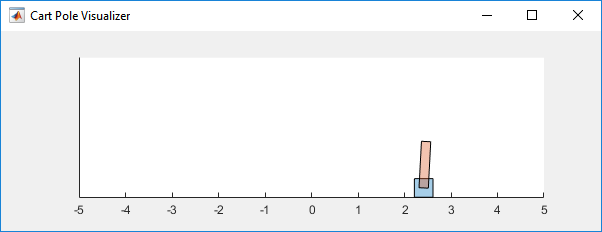

For this environment:

- The upward balanced pole position is 0 radians, and the downward hanging position is `pi` radians.

- The pole starts upright with an initial angle between –0.05 and 0.05 radians.

- The force action signal from the agent to the environment is either –10 or 10 N.

- The observations from the environment are the position and velocity of the cart, the pole angle, and the pole angle derivative.

- The episode terminates if the pole is more than 12 degrees from vertical or if the cart moves more than 2.4 m from the original position.

- A reward of +1 is provided for every time step that the pole remains upright. A penalty of –5 is applied when the pole falls.

For more information on this model, see [Load Predefined Control System Environments](docid:rl_ug#mw_537f0c6d-2ccd-454b-95fa-3ee88ece74aa).

## Create Environment Object

Create a predefined cart-pole environment object.

env = rlPredefinedEnv("CartPole-Discrete")

env =   CartPoleDiscreteAction with properties:

                  Gravity: 9.8000
                 MassCart: 1
                 MassPole: 0.1000
                   Length: 0.5000
                 MaxForce: 10
                       Ts: 0.0200
    ThetaThresholdRadians: 0.2094
               XThreshold: 2.4000
      RewardForNotFalling: 1
        PenaltyForFalling: -5
                    State: [4×1 double]


The interface has a discrete action space where the agent can apply one of two possible force values to the cart, –10 or 10 N.

Get the observation and action specification information. 

obsInfo = getObservationInfo(env)

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "CartPole States"
    Description: "x, dx, theta, dtheta"
      Dimension: [4 1]
       DataType: "double"


actInfo = getActionInfo(env)

actInfo =   rlFiniteSetSpec with properties:

       Elements: [-10 10]
           Name: "CartPole Action"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


## Create DQN Agent

Fix the random stream for reproducibility.

rng(0,"twister");

Create an agent initialization object to initialize the critic network with the hidden layer size 20.

initOpts = rlAgentInitializationOptions(NumHiddenUnit=20);

Specify the agent options for training using [`rlDQNAgentOptions`](docid:rl_ref#mw_d66ae7b0-1964-4f66-a2ee-cfc08fc3657e) and [`rlOptimizerOptions`](docid:rl_ref#mw_18a712bb-b821-4dd9-a7ad-460ad7f2aa03) objects. For this training:

- Use mini-batches of 256 experiences. Smaller mini-batches are computationally efficient but may introduce variance in training. By contrast, larger batch sizes can make the training stable but require higher memory.

- Update the target critic network every 4 learning iterations with a smoothing factor of 1.

- Do not use the double-DQN algorithm.

agentOpts = rlDQNAgentOptions( ...
    MiniBatchSize            = 256,...
    TargetSmoothFactor       = 1, ...
    TargetUpdateFrequency    = 4,...
    UseDoubleDQN             = false);

A DQN agent uses the epsilon-greedy algorithm the explore the action space during training. Specify a decay rate of 1e-3 for the epsilon value to gradually decay during training. This promotes exploration towards the beginning when the agent does not have a good policy, and exploitation towards the end when the agent has learned the optimal policy.

agentOpts.EpsilonGreedyExploration.EpsilonDecay = 1e-3;

Create the DQN agent using the observation and action input specifications, initialization options and agent options. When you create the agent, the initial parameters of the critic network are initialized with random values. Fix the random number stream so that the agent is always initialized with the same parameter values. 

agent = rlDQNAgent(obsInfo,actInfo,initOpts,agentOpts);

For more information, see [`rlDQNAgent`](docid:rl_ref#mw_167d0061-c095-446e-828f-816916a0f227).

Check the agent's actions with a random observation input.

getAction(agent,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[10]}


## Train Agent

Fix the random stream for reproducibility.

rng(0,"twister");

To train the agent, first specify the training options. For this example, use the following options:

- Run the training for at most 1000 episodes, with each episode lasting at most 500 time steps.

- Display the training progress in the Reinforcement Learning Training Monitor window (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Evaluate the performance of the greedy policy every 20 training episodes, averaging the cumulative reward of 5 simulations.

- Stop training when the evaluation score reaches 500. At this point, the agent can balance the cart-pole system in the upright position.

% training options
trainOpts = rlTrainingOptions(...
    MaxEpisodes=1000, ...
    MaxStepsPerEpisode=500, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="EvaluationStatistic",...
    StopTrainingValue=500);

% agent evaluator
evl = rlEvaluator(EvaluationFrequency=20, NumEpisodes=5);

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0) and [`rlEvaluator`](docid:rl_ref#mw_4eee07a3-0481-43f5-b2d2-887af2f09847).

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training this agent is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true;
if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts,Evaluator=evl);
else
    % Load the pretrained agent for the example.
    load("MATLABCartpoleDQNMulti.mat","agent")
end

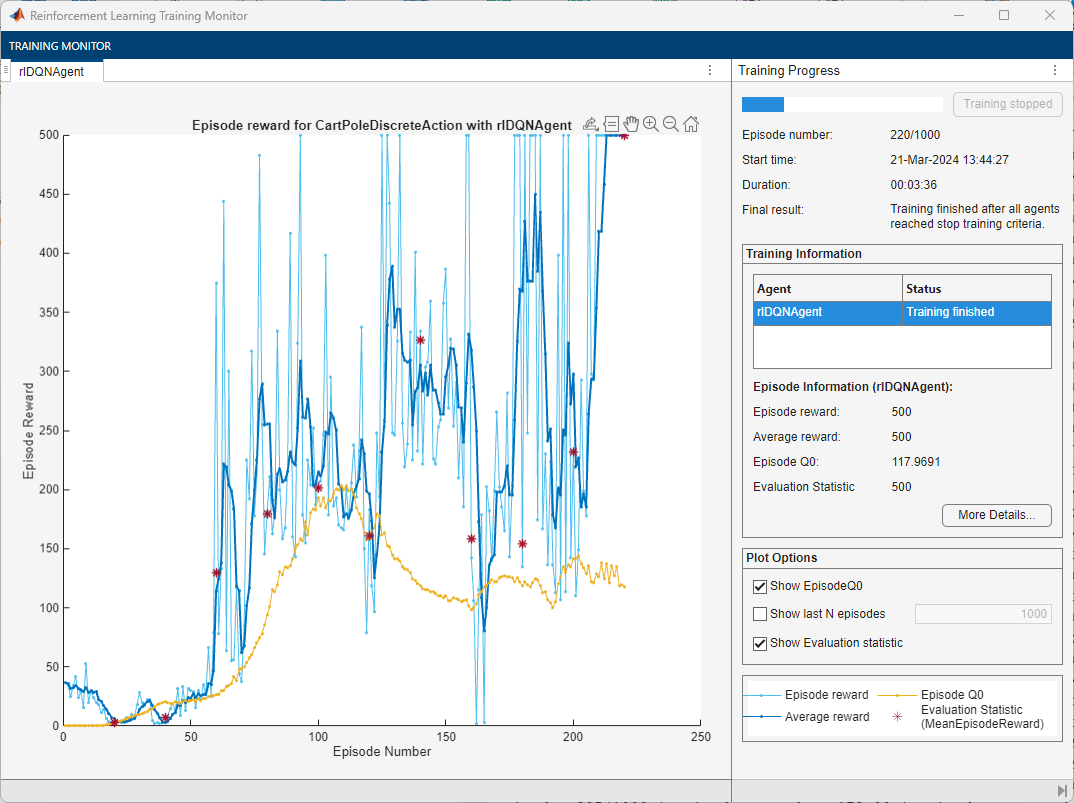

## Simulate Agent

Fix the random stream for reproducibility.

rng(0,"twister");

You can visualize the cart-pole system by using the `plot` function.

plot(env)

To validate the performance of the trained agent, simulate it within the cart-pole environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

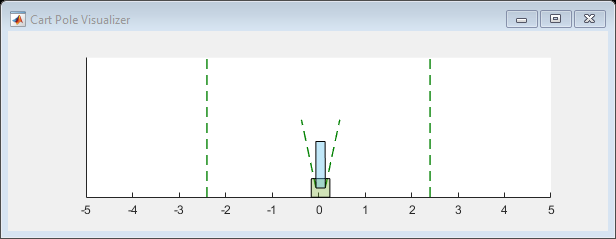

simOptions = rlSimulationOptions(MaxSteps=500);
experience = sim(env,agent,simOptions);

totalReward = sum(experience.Reward)

totalReward = 500

The agent can balance the cart-pole system.

Restore the random number stream using the information stored in `previousRngState`.

rng(previousRngState);

*Copyright 2019-2024 The MathWorks, Inc.*